%Flight Conditions
V = 350 %kts 

V = 350

h = 25000 %ft

h = 25000

DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT
W = 121893*0.946

W = 1.1531e+05


[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
V=V*1.688

V = 590.8000

M = V/SpeedSound

M = 0.5817


%Airfoil Parameters
Cla = 2*pi

Cla = 6.2832

Tmax = 0.15

Tmax = 0.1500

LocMaxT = 0.4

LocMaxT = 0.4000

PerLamFlow = 0.1

PerLamFlow = 0.1000

CLDMin = 0.1

CLDMin = 0.1000


%Planform Parameters
S = 1303; %ft^2
AR = 10.68

AR = 10.6800

AR2 = 5.23

AR2 = 5.2300

b2=100

b2 = 100

TaperRatio = 0.4;
b = sqrt(AR*S)

b = 117.9663

Q = 1.01

Q = 1.0100

SweepQuartC = 0;
e = 0.97;
K = 1/(e*pi*AR)

K = 0.0307


%Fuselage Parameters
Df = 18; %ft
LNose = 16; %ft
LMid = 44; %ft
LTail = 40.3 %ft

LTail = 40.3000

DBase = 4 %ft

DBase = 4

ABase = pi*DBase^2/4

ABase = 12.5664

UpsweepAngle = atan((Df/2-DBase/2)/LTail); %rad

%Vertical Tail Parameters NOTE: Half Wing
Sv = 300*2; %ft^2
ARv = 7.05;
TaperRatiov = 0.55;
bv = sqrt(ARv*Sv);
QVt = 1.05;
LocMaxTv = 0.35;
Tmaxv = 0.12

Tmaxv = 0.1200


%Horizontal Tail Parameters
Sh = 400; %ft^2
ARh = 6.42;
TaperRatioh = 0.35;
bh = sqrt(ARh*Sh);
QHt = 1.05;
LocMaxTh = 0.35;
Tmaxh = 0.12

Tmaxh = 0.1200


%Nacelle Parameters
LNacelle = 78/12;
DNacelle = 34/12;

[CDoWing] = WingZeroLiftDrag(V,Q,TaperRatio,DynVisc,0,S,AR,b,h,LocMaxT,Df,PerLamFlow,Tmax);

V = 997.2704

M = 0.9820

Cr = 15.7793

Cmac = 11.7218

Ymac = 25.2785

SweepMaxT = -1.3792

Cf = 14.3347

Sexp = 1.0320e+03

Re = 6.5269e+07

SweepMaxT = -1.3792

FF = 1.7036

Swet = 2.1207e+03

CDo = 0.0062


[CDoHt] = WingZeroLiftDrag(V,QHt,TaperRatioh,DynVisc,0,Sh,ARh,bh,h,LocMaxTh,0,PerLamFlow,Tmaxh);

V = 997.2704

M = 0.9820

Cr = 11.6939

Cmac = 8.5033

Ymac = 10.6356

SweepMaxT = -1.7183

Cf = 11.6939

Sexp = 400

Re = 4.7348e+07

SweepMaxT = -1.7183

FF = 1.6379

Swet = 815.7600

CDo = 0.0082


CDoHt = CDoHt*Sh/S

CDoHt = 0.0025


[CDoVt] = WingZeroLiftDrag(V,QVt,TaperRatiov,DynVisc,0,Sv,ARv,bv,h,LocMaxTv,0,PerLamFlow,Tmaxv);

V = 997.2704

M = 0.9820

Cr = 11.9036

Cmac = 9.4845

Ymac = 14.6861

SweepMaxT = -0.9437

Cf = 11.9036

Sexp = 600

Re = 5.2812e+07

SweepMaxT = -0.9437

FF = 1.6380

Swet = 1.2236e+03

CDo = 0.0080


CDoVt = CDoVt*Sv/S/2

CDoVt = 0.0019


[CDoFuse] = ParaDragFuse(h,V,LMid,LNose,LTail,Df,DynVisc,S)

FF = 1.3607

CDoFuse = 0.0090


[CDoNacelle] = 8*ParaDragNacelle(h,V,LNacelle,DNacelle,DynVisc,S)

CDoNacelle = 0.0013


UpSweepDrag = 3.83*UpsweepAngle^2.5*pi*Df^2/4/S

UpSweepDrag = 0.0092


CDoCamber = e/(1-e)*K*CLDMin^2

CDoCamber = 0.0099


BaseDrag = (0.1+0.1222*M^8)*ABase/S

BaseDrag = 9.7988e-04


CDoTotal = CDoWing + CDoHt + CDoVt + CDoFuse + UpSweepDrag + BaseDrag + CDoNacelle + CDoCamber

CDoTotal = 0.0410


CDoTotal2 = WingZeroLiftDrag(V,Q,0.4,DynVisc,0,S,AR,b,h,LocMaxT,Df,PerLamFlow,Tmax) + CDoHt + CDoVt + CDoFuse + UpSweepDrag + BaseDrag + CDoNacelle + CDoCamber %0.987/(1-0.987)*K*CLDMin^2

V = 997.2704

M = 0.9820

Cr = 15.7793

Cmac = 11.7218

Ymac = 25.2785

SweepMaxT = -1.3792

Cf = 14.3347

Sexp = 1.0320e+03

Re = 6.5269e+07

SweepMaxT = -1.3792

FF = 1.7036

Swet = 2.1207e+03

CDo = 0.0062

CDoTotal2 = 0.0410


%Induced Drag Factor

% Ne = 4; %Num of engines ON TOP of Wing
% TaperFunc = 0.005*(1+1.5*(TaperRatio-0.6)^2)
% K = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/(cosd(SweepQuartC)^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR)
% e = 1/(K*AR*pi)

CL = -0.5:0.01:1.5

CL =    -0.5000   -0.4900   -0.4800   -0.4700   -0.4600   -0.4500   -0.4400   -0.4300   -0.4200   -0.4100   -0.4000   -0.3900   -0.3800   -0.3700   -0.3600   -0.3500   -0.3400   -0.3300   -0.3200   -0.3100   -0.3000   -0.2900   -0.2800   -0.2700   -0.2600   -0.2500   -0.2400   -0.2300   -0.2200   -0.2100   -0.2000   -0.1900   -0.1800   -0.1700   -0.1600   -0.1500   -0.1400   -0.1300   -0.1200   -0.1100   -0.1000   -0.0900   -0.0800   -0.0700   -0.0600   -0.0500   -0.0400   -0.0300   -0.0200   -0.0100



LDMax = 0;

for x=1:201
    
   CD(x) = CDoTotal + K*CL(x)^2;
   
   if CL(x)/CD(x)>LDMax
       
       LDMax = CL(x)/CD(x)
       
   end
   
end

LDMax = 0.2439

LDMax = 0.4876

LDMax = 0.7312

LDMax = 0.9744

LDMax = 1.2172

LDMax = 1.4594

LDMax = 1.7010

LDMax = 1.9418

LDMax = 2.1817

LDMax = 2.4207

LDMax = 2.6586

LDMax = 2.8954

LDMax = 3.1309

LDMax = 3.3650

LDMax = 3.5976

LDMax = 3.8287

LDMax = 4.0582

LDMax = 4.2859

LDMax = 4.5118

LDMax = 4.7358

LDMax = 4.9578

LDMax = 5.1777

LDMax = 5.3955

LDMax = 5.6111

LDMax = 5.8244

LDMax = 6.0353

LDMax = 6.2438

LDMax = 6.4499

LDMax = 6.6534

LDMax = 6.8543

LDMax = 7.0526

LDMax = 7.2482

LDMax = 7.4410

LDMax = 7.6311

LDMax = 7.8183

LDMax = 8.0027

LDMax = 8.1842

LDMax = 8.3628

LDMax = 8.5384

LDMax = 8.7110

LDMax = 8.8807

LDMax = 9.0473

LDMax = 9.2109

LDMax = 9.3714

LDMax = 9.5289

LDMax = 9.6833

LDMax = 9.8347

LDMax = 9.9829

LDMax = 10.1281

LDMax = 10.2703

LDMax = 10.4093

LDMax = 10.5453

LDMax = 10.6782

LDMax = 10.8081

LDMax = 10.9350

LDMax = 11.0588

LDMax = 11.1796

LDMax = 11.2975

LDMax = 11.4123

LDMax = 11.5243

LDMax = 11.6333

LDMax = 11.7394

LDMax = 11.8426

LDMax = 11.9429

LDMax = 12.0405

LDMax = 12.1353

LDMax = 12.2272

LDMax = 12.3165

LDMax = 12.4031

LDMax = 12.4870

LDMax = 12.5682

LDMax = 12.6469

LDMax = 12.7229

LDMax = 12.7965

LDMax = 12.8676

LDMax = 12.9362

LDMax = 13.0023

LDMax = 13.0661

LDMax = 13.1275

LDMax = 13.1867

LDMax = 13.2435

LDMax = 13.2981

LDMax = 13.3505

LDMax = 13.4008

LDMax = 13.4489

LDMax = 13.4949

LDMax = 13.5389

LDMax = 13.5809

LDMax = 13.6209

LDMax = 13.6590

LDMax = 13.6951

LDMax = 13.7294

LDMax = 13.7619

LDMax = 13.7926

LDMax = 13.8216

LDMax = 13.8488

LDMax = 13.8744

LDMax = 13.8983

LDMax = 13.9207

LDMax = 13.9414

LDMax = 13.9606

LDMax = 13.9783

LDMax = 13.9946

LDMax = 14.0094

LDMax = 14.0228

LDMax = 14.0348

LDMax = 14.0455

LDMax = 14.0549

LDMax = 14.0630

LDMax = 14.0699

LDMax = 14.0755

LDMax = 14.0800

LDMax = 14.0833

LDMax = 14.0855

LDMax = 14.0866

LDMax = 14.0866


K2 = 1/(0.987*pi*AR)

K2 = 0.0302


LDMax2 = 0;

for x=1:201
    
   CD2(x) = CDoTotal2 + K2*CL(x)^2;
   
   if CL(x)/CD(x)>LDMax2
       
       LDMax2 = CL(x)/CD2(x)
       
   end
   
end

LDMax2 = 0.2439

LDMax2 = 0.4876

LDMax2 = 0.7312

LDMax2 = 0.9744

LDMax2 = 1.2172

LDMax2 = 1.4594

LDMax2 = 1.7011

LDMax2 = 1.9419

LDMax2 = 2.1820

LDMax2 = 2.4210

LDMax2 = 2.6591

LDMax2 = 2.8959

LDMax2 = 3.1315

LDMax2 = 3.3658

LDMax2 = 3.5987

LDMax2 = 3.8300

LDMax2 = 4.0597

LDMax2 = 4.2876

LDMax2 = 4.5138

LDMax2 = 4.7381

LDMax2 = 4.9605

LDMax2 = 5.1808

LDMax2 = 5.3990

LDMax2 = 5.6151

LDMax2 = 5.8289

LDMax2 = 6.0403

LDMax2 = 6.2494

LDMax2 = 6.4561

LDMax2 = 6.6602

LDMax2 = 6.8618

LDMax2 = 7.0608

LDMax2 = 7.2571

LDMax2 = 7.4507

LDMax2 = 7.6416

LDMax2 = 7.8297

LDMax2 = 8.0149

LDMax2 = 8.1973

LDMax2 = 8.3768

LDMax2 = 8.5534

LDMax2 = 8.7271

LDMax2 = 8.8978

LDMax2 = 9.0655

LDMax2 = 9.2302

LDMax2 = 9.3919

LDMax2 = 9.5506

LDMax2 = 9.7062

LDMax2 = 9.8588

LDMax2 = 10.0083

LDMax2 = 10.1548

LDMax2 = 10.2983

LDMax2 = 10.4386

LDMax2 = 10.5760

LDMax2 = 10.7103

LDMax2 = 10.8416

LDMax2 = 10.9699

LDMax2 = 11.0952

LDMax2 = 11.2175

LDMax2 = 11.3368

LDMax2 = 11.4531

LDMax2 = 11.5666

LDMax2 = 11.6771

LDMax2 = 11.7847

LDMax2 = 11.8895

LDMax2 = 11.9915

LDMax2 = 12.0906

LDMax2 = 12.1869

LDMax2 = 12.2805

LDMax2 = 12.3713

LDMax2 = 12.4595

LDMax2 = 12.5450

LDMax2 = 12.6278

LDMax2 = 12.7081

LDMax2 = 12.7858

LDMax2 = 12.8610

LDMax2 = 12.9336

LDMax2 = 13.0038

LDMax2 = 13.1370

LDMax2 = 13.2607

LDMax2 = 13.3753

LDMax2 = 13.4811

LDMax2 = 13.5783

LDMax2 = 13.6673

LDMax2 = 13.7861

LDMax2 = 13.8879

LDMax2 = 13.9992

LDMax2 = 14.1182

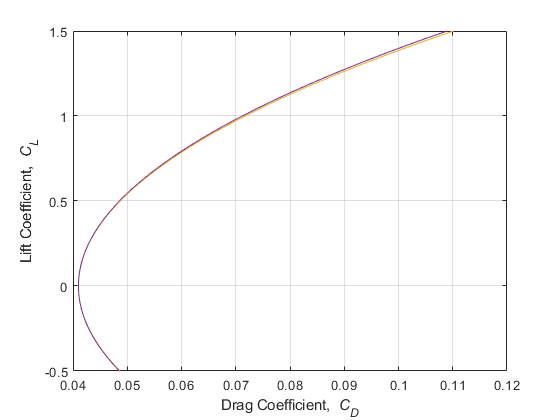


plot (CD,CL)
hold on
plot (CD2,CL)
xlabel('Drag Coefficient, {\it C_{D}}')
ylabel('Lift Coefficient, {\it C_{L}}')
grid on


LDMax

LDMax = 14.0866